# Create Partial Dependence Plot

Train a regression tree using the `carsmall` data set, and create a PDP that shows the relationship between a feature and the predicted responses in the trained regression tree. 

Load the `carsmall` data set.

load carsmall

Specify `Weight`, `Cylinders`, and `Horsepower` as the predictor variables (`X`), and `MPG` as the response variable (`Y`).

X = [Weight,Cylinders,Horsepower];
Y = MPG;

Train a regression tree using `X` and `Y`.

Mdl = fitrtree(X,Y);

View a graphical display of the trained regression tree.

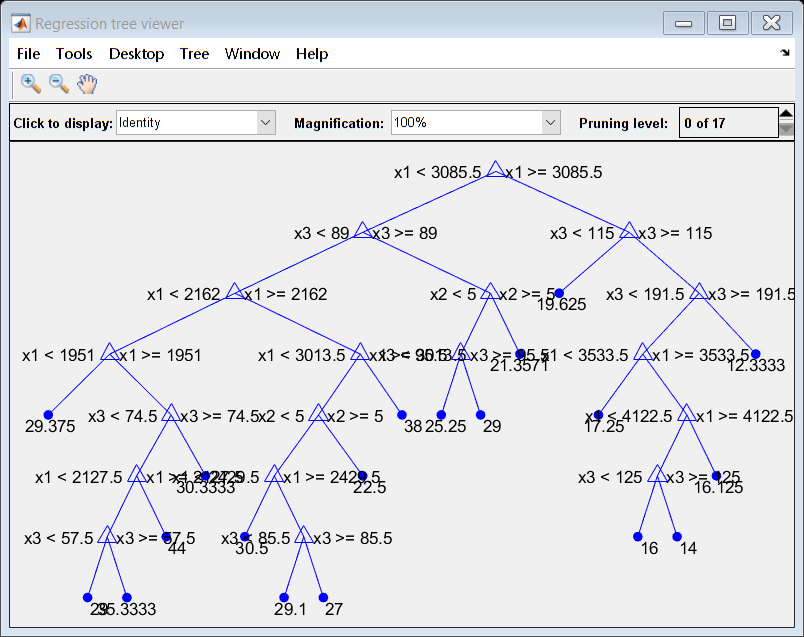

view(Mdl,'Mode','graph')

Create a PDP of the first predictor variable, `Weight`.

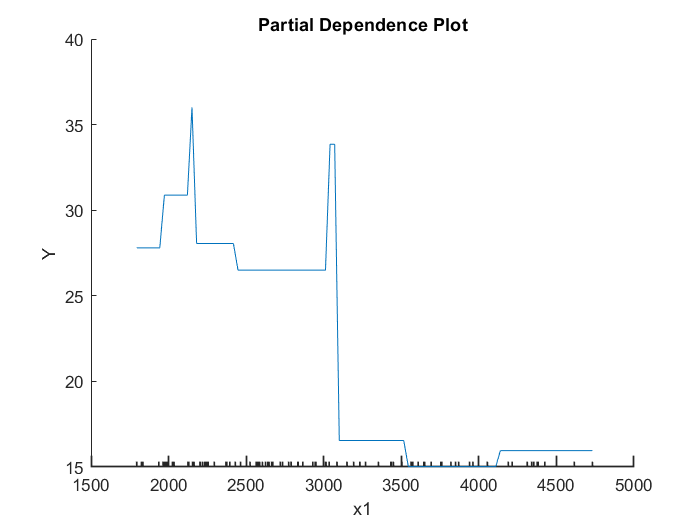

plotPartialDependence(Mdl,1)

The plotted line represents averaged partial relationships between `Weight` (labeled as `x1`) and `MPG` (labeled as `Y`) in the trained regression tree `Mdl`. The `x`-axis minor ticks represent the unique values in `x1`.

The regression tree viewer shows that the first decision is whether `x1` is smaller than 3085.5. The PDP also shows a large change near `x1` = 3085.5. The tree viewer visualizes each decision at each node based on predictor variables. You can find several nodes split based on the values of `x1`, but determining the dependence of `Y` on `x1` is not easy. However, the `plotPartialDependence` plots average predicted responses against `x1`, so you can clearly see the partial dependence of `Y` on `x1`.

The labels `x1` and `Y` are the default values of the predictor names and the response name. You can modify these names by specifying the name-value pair arguments `'PredictorNames'` and `'ResponseName'` when you train `Mdl` using `fitrtree`. You can also modify axis labels by using the [`xlabel`](docid:matlab_ref.btpmg0w-1) and [`ylabel`](docid:matlab_ref.buiyzbx-1) functions.

*Copyright 2017 The MathWorks, Inc.*